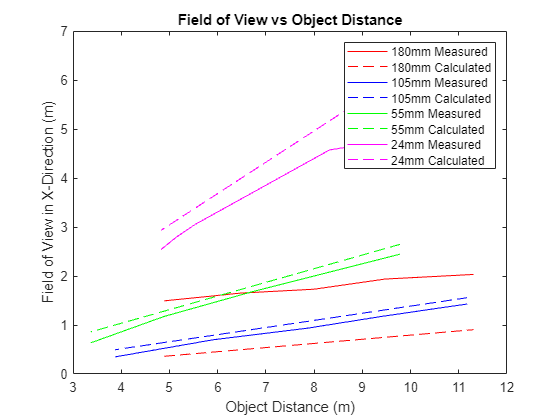

clear; clc;
X=1280;
Y=1024;
R=Y/X;
%% 105mm Camera Lens %%
z_total_105=4.384*0.254;
z_105=z_total_105/2;
f_105=0.105;
% FOV vs Z
Z_1_105=44*0.254;
FOVx_1_105=(5+5/8)*0.254;
Z_2_105=37*0.254;
FOVx_2_105=(4+5/8)*0.254;
Z_3_105=31*0.254;
FOVx_3_105=(3+11/16)*0.254;
Z_4_105=(23+1/4)*0.254;
FOVx_4_105=(2+3/4)*0.254;
Z_5_105=(15+1/4)*0.254;
FOVx_5_105=(1+3/8)*0.254;
Z_105=[Z_1_105 Z_2_105 Z_3_105 Z_4_105 Z_5_105];
FOVx_105=[FOVx_1_105 FOVx_2_105 FOVx_3_105 FOVx_4_105 FOVx_5_105];
FOVy_105=FOVx_105.*R;
% f number vs DOF
fn_1_105=16;
DOF_1_105=(6+1/2)*0.254;
fn_2_105=8;
DOF_2_105=3*0.254;
fn_3_105=2.8;
DOF_3_105=1*0.254;
fn_105=[fn_1_105 fn_2_105 fn_3_105];
DOF_105=[DOF_1_105 DOF_2_105 DOF_3_105];
N_105=f_105./(fn_105.*10^-3);
Z_105d=44*0.254;
% Bellows z vs FOV
z_2_105=(9.5*0.254)-z_105;
Z_2_105b=16*0.254;
FOVx_2b_105=(23/32)*0.254;
z_1_105=(9.75*0.254)- z_105;
Z_1_105b=15.75*0.254;
FOVx_1b_105=(20/32)*0.254;
z_3_105=(10.75*0.254)- z_105;
Z_3_105b=16.125*0.254;
FOVx_3b_105=(15/32)*0.254;
z_5_105=(12*0.254)- z_105;
Z_5_105b=16.75*0.254;
FOVx_5b_105=(12/32)*0.254;
z_4_105=(8.25*0.254)- z_105;
Z_4_105b=16.25*0.254;
FOVx_4b_105=(26/32)*0.254;
z_105b=[ z_1_105 z_2_105 z_3_105 z_4_105 z_5_105];
FOVx_105b=[FOVx_1b_105 FOVx_2b_105 FOVx_3b_105 FOVx_4b_105 FOVx_5b_105];
FOVx_105b=FOVx_105b*2;
FOVy_105b=FOVx_105b.*R;
Z_105b=[Z_1_105b Z_2_105b Z_3_105b Z_4_105b Z_5_105b];
%% 180mm Camera Lens %%
z_total_180=5.915*0.254;
z_180=z_total_180/2;
f_180=0.180;
% FOV vs Z
Z_1_180=19.25*0.254;
FOVx_1_180=(5+7/8)*0.254;
Z_2_180=25.5*0.254;
FOVx_2_180=(6.5)*0.254;
Z_3_180=31.5*0.254;
FOVx_3_180=(6+13/16)*0.254;
Z_4_180=(37+1/4)*0.254;
FOVx_4_180=(7+5/8)*0.254;
Z_5_180=(44+1/2)*0.254;
FOVx_5_180=8*0.254;
Z_180=[Z_1_180 Z_2_180 Z_3_180 Z_4_180 Z_5_180];
FOVx_180=[FOVx_1_180 FOVx_2_180 FOVx_3_180 FOVx_4_180 FOVx_5_180];
FOVy_180=FOVx_180.*R;
% f number vs DOF
fn_1_180=2.8;
DOF_1_180=(2+1/4)*0.254;
fn_2_180=4;
DOF_2_180=(4+1/4)*0.254;
fn_3_180=8;
DOF_3_180=9*0.254;
fn_4_180=22;
DOF_4_180=(11+3/4)*0.254;
fn_180=[fn_1_180 fn_2_180 fn_3_180 fn_4_180];
DOF_180=[DOF_1_180 DOF_2_180 DOF_3_180 DOF_4_180];
N_180=f_180./(fn_180.*10^-3);
Z_180d=44.5*0.254;
% Bellows z vs FOV
z_1_180=((9+3/4)*0.254)-z_180;
Z_1_180b=30.5*0.254;
FOVx_1b_180=(1+4/16)*0.254;
z_2_180=(10.25*0.254)- z_180;
Z_2_180b=30.25*0.254;
FOVx_2b_180=(1+2/16)*0.254;
z_3_180=(11.75*0.254)- z_180;
Z_3_180b=28.5*0.254;
FOVx_3b_180=(28/32)*0.254;
z_4_180=(12.75*0.254)- z_180;
Z_4_180b=27.75*0.254;
FOVx_4b_180=(24/32)*0.254;
z_5_180=(13.5*0.254)- z_180;
Z_5_180b=27.5*0.254;
FOVx_5b_180=(20/32)*0.254;
z_180b=[z_1_180 z_2_180 z_3_180 z_4_180 z_5_180];
FOVx_180b=[FOVx_1b_180 FOVx_2b_180 FOVx_3b_180 FOVx_4b_180 FOVx_5b_180];
FOVx_180b=FOVx_180b*2;
FOVy_180b=FOVx_180b.*R;
Z_180b=[Z_1_180b Z_2_180b Z_3_180b Z_4_180b Z_5_180b];
%% 55mm Camera Lens %%
z_total_55=2.494*0.254;
z_55=z_total_55/2;
f_55=0.055;
% FOV vs Z
Z_1_55=38.5*0.254;
FOVx_1_55=(9+(5/8))*0.254;
Z_2_55=33.25*0.254;
FOVx_2_55=(8+(5/16))*0.254;
Z_3_55=26.5*0.254;
FOVx_3_55=(6+(5/8))*0.254;
Z_4_55=(19.25)*0.254;
FOVx_4_55=(4+(5/8))*0.254;
Z_5_55=(13+(1/4))*0.254;
FOVx_5_55=2.5*0.254;
Z_55=[Z_1_55 Z_2_55 Z_3_55 Z_4_55 Z_5_55];
FOVx_55=[FOVx_1_55 FOVx_2_55 FOVx_3_55 FOVx_4_55 FOVx_5_55];
FOVy_55=FOVx_55.*R;
% f number vs DOF
fn_1_55=3.5;
DOF_1_55=(1)*0.254;
fn_2_55=8;
DOF_2_55=(1+3/4)*0.254;
fn_3_55=22;
DOF_3_55=5*0.254;
fn_55=[fn_1_55 fn_2_55 fn_3_55];
DOF_55=[DOF_1_55 DOF_2_55 DOF_3_55];
N_55=f_55./(fn_55.*10^-3);
Z_55d=38.5*0.254;
%% 24mm Camera Lens %%
z_total_24=2.017*0.254;
z_24=z_total_24/2;
f_24=0.024;
% FOV vs Z
Z_3_24=21.75*0.254;
FOVx_3_24=(12)*0.254;
Z_4_24=20.25*0.254;
FOVx_4_24=(11)*0.254;
Z_5_24=19*0.254;
FOVx_5_24=(10)*0.254;
Z_2_24=(32+3/4)*0.254;
FOVx_2_24=(18)*0.254;
Z_1_24=(39)*0.254;
FOVx_1_24=19*0.254;
Z_24=[Z_1_24 Z_2_24 Z_3_24 Z_4_24 Z_5_24];
FOVx_24=[FOVx_1_24 FOVx_2_24 FOVx_3_24 FOVx_4_24 FOVx_5_24];
FOVy_24=FOVx_24.*R;
% f number vs DOF
fn_1_24=2.8;
DOF_1_24=(2)*0.254;
fn_2_24=8;
DOF_2_24=(8)*0.254;
fn_3_24=22;
DOF_3_24=14*0.254;
fn_24=[fn_1_24 fn_2_24 fn_3_24];
DOF_24=[DOF_1_24 DOF_2_24 DOF_3_24];
N_24=f_24./(fn_24.*10^-3);
Z_24d=39*0.254;
%% Calculating FOV and DOV %%
c=0.005; % Used Circle of Confusion from Fujifilm FinePix S1500 on https://www.dofmaster.com/digital_coc.html
dx=12*(10^-6)*1280; % It is a PCO 1200, from data sheet on https://www.findlight.net/imaging-and-vision/cameras/imaging-spectroscopy/pco-1200-hspco-1200-s-cmos-camera-system
dy=dx*R;
FOVx_180_calc=(dx./(f_180.*(Z_180+z_180))).*(Z_180).^2;
FOVx_105_calc=(dx./(f_105.*(Z_105+z_105))).*(Z_105).^2;
FOVx_55_calc=(dx./(f_55.*(Z_55+z_55))).*(Z_55).^2;
FOVx_24_calc=(dx./(f_24.*(Z_24+z_24))).*(Z_24).^2;
DOF_180_calc=((Z_180d.*((f_180)^2))./((f_180^2)-(N_180.*c.*(Z_180d-f_180))))-(Z_180d.*(f_180)^2)./((f_180^2)+(N_180.*c.*(Z_180d-f_180)));
DOF_180_calc=abs(DOF_180_calc);
DOF_105_calc=((Z_105d.*((f_105)^2))./((f_105^2)-(N_105.*c.*(Z_105d-f_105))))-(Z_105d.*(f_105)^2)./((f_105^2)+(N_105.*c.*(Z_105d-f_105)));
DOF_105_calc=abs(DOF_105_calc);
DOF_55_calc=((Z_55d.*((f_55)^2))./((f_55^2)-(N_55.*c.*(Z_55d-f_55))))-(Z_55d.*(f_55)^2)./((f_55^2)+(N_55.*c.*(Z_55d-f_55)));
DOF_55_calc=abs(DOF_55_calc);
DOF_24_calc=((Z_24d.*((f_24)^2))./((f_24^2)-(N_24.*c.*(Z_24d-f_24))))-(Z_24d.*(f_24)^2)./((f_24^2)+(N_24.*c.*(Z_24d-f_24)));
DOF_24_calc=abs(DOF_24_calc);
FOVx_180_calcb=(dx./(f_180.*(Z_180b+z_180b))).*(Z_180b).^2;
FOVx_105_calcb=(dx./(f_105.*(Z_105b+z_105b))).*(Z_105b).^2;
%% Plotting Results %%
figure (1)
plot(Z_180,FOVx_180,'r',Z_180,FOVx_180_calc,'r--',Z_105,FOVx_105,'b',Z_105,FOVx_105_calc,'b--',Z_55,FOVx_55,'g',Z_55,FOVx_55_calc,'g--',Z_24,FOVx_24,'m',Z_24,FOVx_24_calc,'m--')
xlabel('Object Distance (m)'),ylabel('Field of View in X-Direction (m)')
legend('180mm Measured','180mm Calculated','105mm Measured','105mm Calculated','55mm Measured','55mm Calculated','24mm Measured','24mm Calculated')
title('Field of View vs Object Distance')

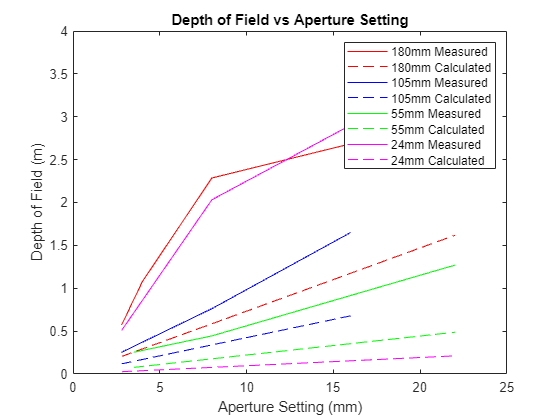

figure (2)
plot(fn_180,DOF_180,'r',fn_180,DOF_180_calc,'r--',fn_105,DOF_105,'b',fn_105,DOF_105_calc,'b--',fn_55,DOF_55,'g',fn_55,DOF_55_calc,'g--',fn_24,DOF_24,'m',fn_24,DOF_24_calc,'m--')
xlabel('Aperture Setting (mm)'),ylabel('Depth of Field (m)')
legend('180mm Measured','180mm Calculated','105mm Measured','105mm Calculated','55mm Measured','55mm Calculated','24mm Measured','24mm Calculated')
title('Depth of Field vs Aperture Setting')

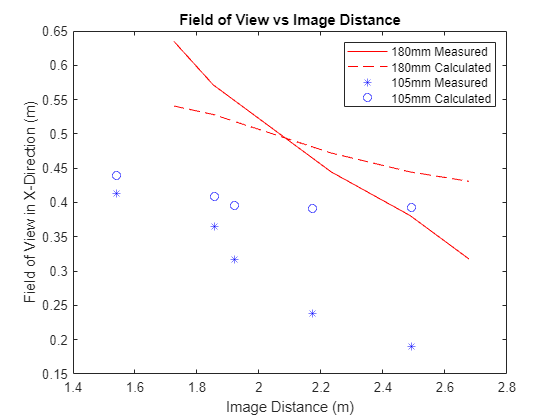

figure (3)
plot(z_180b,FOVx_180b,'r',z_180b,FOVx_180_calcb,'r--',z_105b,FOVx_105b,'b*',z_105b,FOVx_105_calcb,'bo')
xlabel('Image Distance (m)'),ylabel('Field of View in X-Direction (m)')
legend('180mm Measured','180mm Calculated','105mm Measured','105mm Calculated')
title('Field of View vs Image Distance')